# Trabajo práctico: Controladores PID

clear;

## 1) Open loop control

Se propone el control a lazo abierto de un sistema de velocidad crucero. El objetivo del control es seguir la velocidad de referencia proporcionada. La perturbación del sistema está dada por un cambio en el ángulo del terreno ($\alpha$).

El modelo matemático de la planta está dado por:

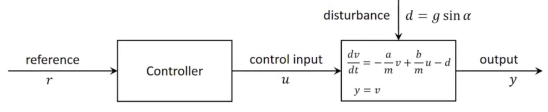

m = 1000;   % Kg
g = 9.82;   % m/s^2
a = 200;    % N/rad
b = 10000;  % Ns/m

En el siguiente modelo de control de velocidad crucero,

#### a) Proponga una ley de control.

La ley de control es de la forma: $u(t) = \frac{a}{b}r(t)$

#### b) Se aplica un escalón a los 10 segundos que va de 25 m/s a 30 m/s. Verifique la respuesta del sistema con control a lazo abierto ¿Es satisfactoria?

t0 = 10;    % s
v0 = 25;    % m/s
v1 = 30;    % m/s

La respuesta es **satisfactoria** ya que sigue la consigna. Sin embargo la respuesta es relativamente lenta, alcanzando la referencia a los 25 segundos de aplicado el escalón.

#### c) Agregue una perturbación de 2 grados de inclinación en el terreno a los 20 segundos de simulación. Analice la respuesta del sistema ¿Es satisfactoria?

alpha = deg2rad(2);
d = g*sin(alpha);
td = 20;    % s

La respuesta **no es satisfactoria** ya que al producirse la perturbación no hay acción de control que la corrija y el sistema queda estacionario en un punto distinto al de referencia.

#### d) Cambie el valor de la masa a 1500 Kg. Analice nuevamente la respuesta del sistema ¿Es satisfactoria?

m = 1500;   % Kg

La respuesta **no es satisfactoria**. Con perturbación el sistema sigue teniendo un error de estado estacionario, y sin ella puede observarse que al aumentar la masa del sistema la respuesta es aún más lenta de lo que ya era.

#### e) ¿Qué conclusiones se derivan de la simulación de este modelo?

Ante un control a lazo abierto el sistema puede seguir la consigna **en simulación**, ya que los parámetros utilizados son *perfectos* algo muy lejano en la práctica. La respuesta es muy lenta, aunque este aspecto podría mejorarse con un controlador a lazo abierto más avanzado. Sin embargo, la mayor desventaja del lazo abierto es que no puede reaccionar ante perturbaciones. Esto produce un error de estado estacionario en la salida que no es posible corregir.

## 2) Close loop P control

Aborde el control del sistema del Ejercicio 1 pero utilizando un controlador P.

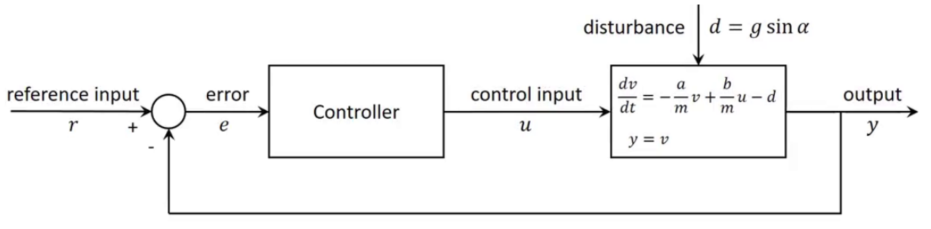

Nuevamente,

m = 1000;   % Kg

#### a) Analice la respuesta del sistema utilizando solo control proporcional (P) con kp = 1.

kp = 1;

#### b) Se aplica un escalón a los 10 segundos que va de 25 m/s a 30 m/s. Verifique la respuesta del sistema con control a lazo cerrado ¿Es satisfactoria?

La respuesta **no es satisfactoria**, ya que se observa como existe un error a lo largo de toda la consigna.

#### c) Agregue una perturbación de 2 grados de inclinación en el terreno a los 20 segundos de simulación. Analice la respuesta del sistema ¿Es satisfactoria?

La respuesta **no es satisfactoria**, ya que permanece el error antes mencionado. Sí se puede observar que la perturbación no produce efecto en el error.

#### d) Cambie el valor de la masa a 1500 kg. Analice nuevamente la respuesta del sistema ¿Es satisfactoria?

m = 1500;

#### e) ¿Qué conclusiones se derivan de la simulación de este modelo?

Plantear un controlador solo P no es suficiente, ya que no permite seguir la consigna planteada.

## 3) Close loop PI control

Aborde el control del sistema del Ejercicio 1 pero utilizando un controlador PI.

Nuevamente,

#### a) Analice la respuesta del sistema utilizando solo control PI con kp = 1 y ki = 0.1.

ki = 0.1;

#### b) Se aplica un escalón a los 10 segundos que va de 25 m/s a 30 m/s. Verifique la respuesta del sistema con control a lazo cerrado ¿Es satisfactoria?

La respuesta es **satisfactoria**. Se puede observar que es mucho más rápida en comparación con la respuesta a lazo abierto, y se elimina el error de estado estacionario que se obtenía en el controlador P.

#### c) Agregue una perturbación de 2 grados de inclinación en el terreno a los 20 segundos de simulación. Analice la respuesta del sistema ¿Es satisfactoria?

La respuesta es **satisfactoria**. Se sigue la consigna, eliminando el error de estado estacionario del controlador solo P, y también se corrije la salida al producirse la perturbación.

#### d) Cambie el valor de la masa a 1500 kg. Analice nuevamente la respuesta del sistema ¿Es satisfactoria?

m = 1500;   % Kg

La respuesta es **satisfactoria**, aunque puede observarse como se llega en más tiempo a la referencia (respuesta más lenta).

#### e) ¿Qué conclusiones se derivan de la simulación de este modelo?

El control cumple el seguimiento de la consigna o referencia, eliminando el error de estado estacionario del controlador solo P, y corrijiendo la salida ante la existencia de perturbaciones. Sin embargo, aunque la respuesta es más rápida que la obtenida para un lazo abierto, los tiempos requeridos para llegar a la referencia son considerablemente largos.

clear all;

## 4) Configuración del controlador PID por ubicación de polos

Determine en forma simbólica la ecuación de transferencia del sistema a lazo cerrado de la planta del Ejercicio 1 en función de los valores de a, b, m, kp, ki y kd, donde la ecuación del PID está dada por


$$PID(s) = kp + \frac{ki}{s} + kd\cdot s$$


Encuentre la ecuación característica del sistema y analice los polos del sistema.

Determine los valores de kp, ki y kd en función de a, b y m según el método de ubicación de polos. Considere que se desea que todos los polos sean iguales.

syms s a b m kp ki kd r;            % Siendo r ubicación deseada sobre eje real
GC = kp + ki/s + kd*s;              % Función de transferencia del controlador
GS = (b/m)/(s + a/m);               % Función de transferencia de la planta
H = simplify(GC*GS/(1 + GC*GS));    % Función de transferencia del sistema a lazo cerrado
disp(H);

$$\frac{b\,\left(\mathrm{kd}\,s^{2}+\mathrm{kp}\,s+\mathrm{ki}\right)}{b\,\mathrm{ki}+a\,s+m\,s^{2}+b\,\mathrm{kp}\,s+b\,\mathrm{kd}\,s^{2}}$$

[NUM, DEN] = numden(H);
disp(DEN);

$$b\,\mathrm{ki}+a\,s+m\,s^{2}+b\,\mathrm{kp}\,s+b\,\mathrm{kd}\,s^{2}$$

COEFF1 = fliplr(coeffs(DEN, s));    % Coeficientes obtenidos
COEFF2 = fliplr(coeffs((s - r)^2, s)); % Coeficientes deseados
S = COEFF1 == COEFF2;
disp(S);

$$\left(\begin{array}{ccc} m+b\,\mathrm{kd}=1 & a+b\,\mathrm{kp}=-2\,r & b\,\mathrm{ki}=r^{2} \end{array}\right)$$

Siendo los valores numéricos:

m = 1000;   % Kg
g = 9.82;   % m/s^2
a = 200;    % N/rad
b = 10000;  % Ns/m
r = 1500;

Las constantes del controlador serán:

S = subs(S);    % Sustitución por valores numéricos
kd = abs(eval(solve(S(1), kd)));
kp = abs(eval(solve(S(2), kp)));
ki = abs(eval(solve(S(3), ki)));

Datos de la entrada y la perturbación:

t0 = 10;    % s
v0 = 25;    % m/s
v1 = 30;    % m/s
alpha = deg2rad(2);
d = g*sin(alpha);
td = 20;    % s